clc; clear; close all;

global solver

solver = 1  % 多项式

solver = 1

[solutionPol, grid] = solver1D()

solutionPol =     0.5749    0.7278    0.8326    0.9003    0.9423    0.9676    0.9822    0.9905    0.9951    0.9976    0.9989    0.9996    1.0000    1.0001    1.0001    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0001    1.0002    1.0001    0.9998    0.9989    0.9972    0.9941    0.9886    0.9791    0.9630    0.9365    0.8942    0.8291    0.7327    0.5963


grid =     0.0050    0.0150    0.0250    0.0350    0.0450    0.0550    0.0650    0.0750    0.0850    0.0950    0.1050    0.1150    0.1250    0.1350    0.1450    0.1550    0.1650    0.1750    0.1850    0.1950    0.2050    0.2150    0.2250    0.2350    0.2450    0.2550    0.2650    0.2750    0.2850    0.2950    0.3050    0.3150    0.3250    0.3350    0.3450    0.3550    0.3650    0.3750    0.3850    0.3950    0.4050    0.4150    0.4250    0.4350    0.4450    0.4550    0.4650    0.4750    0.4850    0.4950



solver = 2  % 多项式

solver = 2

[solutionExp, ~] = solver1D()

solutionExp =     0.6156    0.7047    0.7787    0.8382    0.8845    0.9194    0.9450    0.9633    0.9760    0.9846    0.9903    0.9941    0.9964    0.9980    0.9989    0.9995    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0001    1.0002    1.0002    0.9999    0.9989    0.9955    0.9843    0.9475    0.8470    0.7235    0.6021    0.4876


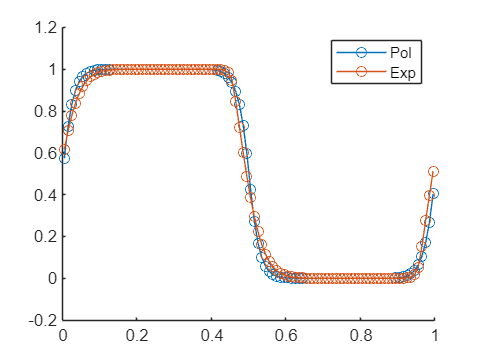


figure
hold on
plot(grid, solutionPol, 'o-', 'DisplayName', 'Pol')
plot(grid, solutionExp, 'o-', 'DisplayName', 'Exp')
legend


% save('solution.mat', 'solution', 'x_grid');

function [solution, grid] = solver1D()
% solver1D - 一维守恒律数值求解器 (RK3 + 有限体积)
%
% 本函数自带所有参数设置，不依赖外部变量

    % 通量函数 & 导数
    f = @(x) x;                    
    g = @(x) 1;                    

    % 初始条件
    u0 = @(x) 1*(x>0.5);         

    % 计算区域 & 终止时间
    domain_left  = 0;              
    domain_right = 1;              
    final_time   = 0.5;            

    % 网格 & 时间参数
    mesh_points = 100;             
    time_step   = 1e-4;            
    num_time_steps = round(final_time / time_step);

    % 网格与空间步长
    space_step = (domain_right - domain_left) / mesh_points;
    x_grid = domain_left:space_step:domain_right;

    % 初值：单元平均值
    solution = zeros(1, mesh_points);
    for j = 1:mesh_points
        solution(j) = integral(u0, x_grid(j), x_grid(j+1)) / space_step;
    end

    % 时间推进（RK3）
    for t = 1:num_time_steps
        % RK3 第一步
        k1 = solution + time_step * getL(solution, f, g, space_step);

        % RK3 第二步
        k2 = 3/4 * solution + 1/4 * k1 + ...
            1/4 * time_step * getL(k1, f, g, space_step);

        % RK3 第三步
        solution = 1/3 * solution + 2/3 * k2 + ...
            2/3 * time_step * getL(k2, f, g, space_step);
    end
    
    grid = x_grid(1:end-1)+diff(x_grid)/2;

end